% Load the data and remove outliers
[x_data, y_data] = set_2_col_vec(filename, 'frequency', 'power', directory);
prctiles = prctile(y_data, [0.8 98.5]);
y_data(y_data < prctiles(1) | y_data > prctiles(2)) = NaN;

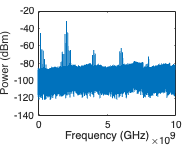


% Plot the data
plot(x_data, y_data);
xlabel('Frequency (GHz)');
ylabel('Power (dBm)');

   1.0e+09 *

    2.0000
    2.1000
    0.1000
    1.9000
    6.0000
    0.2000
    4.0000
    2.3000
    0.3000
    2.2000
    5.9000
    1.7000
    6.1000
    4.1000
    1.8000
    3.9000
    8.0000
    6.9600
    7.1000
    7.0400



  -31.3969
  -44.5449
  -45.0400
  -46.1466
  -62.2555
  -63.7153
  -64.5569
  -64.6273
  -65.1319
  -65.2277
  -66.0937
  -66.5364
  -67.0286
  -68.6423
  -69.1699
  -70.3158
  -71.9114
  -77.0740
  -77.8094
  -77.8421



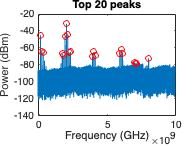

   1.0e+09 *

    2.0000
    2.1000
    0.1000
    1.9000
    6.0000
    0.2000
    4.0000
    2.3000
    0.3000
    2.2000
    5.9000
    1.7000
    6.1000
    4.1000
    1.8000



  -31.3969
  -44.5449
  -45.0400
  -46.1466
  -62.2555
  -63.7153
  -64.5569
  -64.6273
  -65.1319
  -65.2277
  -66.0937
  -66.5364
  -67.0286
  -68.6423
  -69.1699



Peak coordinates:


   1.0e+09 *

    2.0000
    2.1000
    0.1000
    1.9000
    6.0000
    0.2000
    4.0000
    2.3000
    0.3000
    2.2000
    5.9000
    1.7000
    6.1000
    4.1000
    1.8000



  -31.3969
  -44.5449
  -45.0400
  -46.1466
  -62.2555
  -63.7153
  -64.5569
  -64.6273
  -65.1319
  -65.2277
  -66.0937
  -66.5364
  -67.0286
  -68.6423
  -69.1699




% Ask the user for the desired number of peaks
num_peaks = 0;
while true
    num_peaks_input = input(sprintf('Enter the desired number of peaks (currently %d): ', num_peaks));
    if isempty(num_peaks_input) % use previous value if no input is given
        num_peaks_input = num_peaks;
    end
    num_peaks = num_peaks_input;

    % Find the peaks
    [pks, locs] = findpeaks(y_data);

    % Get the indices of the top num_peaks peaks
    [~, sorted_indices] = sort(y_data(locs), 'descend');
    peak_indices = locs(sorted_indices(1:num_peaks));

    % Get the coordinates of the top num_peaks peaks
    x_peaks = x_data(peak_indices);
    y_peaks = y_data(peak_indices);

    % Plot the data with the peaks marked
    figure;
    plot(x_data, y_data);
    hold on;
    plot(x_peaks, y_peaks, 'ro');
    hold off;

    % Ask the user if the plot is acceptable
    response = input('Is the plot acceptable? [y/n]: ', 's');
    if strcmpi(response, 'y') % plot is acceptable, break out of loop
        break;
    end
end

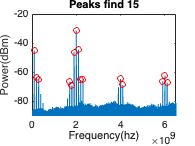

% Ask the user if they want to save the plot
response = input('Do you want to save the plot? [y/n]: ', 's');
if strcmpi(response, 'y')
    % Prompt for x and y limits, x label, y label, and title
    x_limits = input('Enter the x limits (e.g. [0 2]): ');
    y_limits = input('Enter the y limits (e.g. [-50 0]): ');
    x_label = input('Enter the x label: ', 's');
    y_label = input('Enter the y label: ', 's');
    plot_title = input('Enter the plot title: ', 's');
    
    % Save the plot
    xlim(x_limits);
    ylim(y_limits);
    xlabel(x_label);
    ylabel(y_label);
    title(plot_title);
    saveas(gcf, 'plot.png');
end